## Set paths

rootdir = '/Users/nbertelsen/projects/cmi_eeg_rs_H';
resultsdir = fullfile(rootdir, "results/reval/global");
plotdir = fullfile(rootdir, "plots/reval/global");
eeglabdir = '/Users/nbertelsen/Documents/MATLAB/eeglab_20201226'; 

## Initiate eeglab

cd(eeglabdir), eeglab('nogui'); cd(rootdir)

eeglab: options file is ~/eeg_options.m
EEGLAB: adding "Adjust" v1.1.1 (see >> help eegplugin_adjust)
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "Cleanline" v1.04 (see >> help eegplugin_cleanline)
EEGLAB: adding "EEGBrowser" v? (see >> help eegplugin_EEGBrowser)
EEGLAB: adding "FASTER1.2.3b" v? (see >> help eegplugin_FASTER)
EEGLAB: adding "Fieldtrip-lite" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ICLabel" v? (see >> help eegplugin_iclabel)
EEGLAB: adding "IC_MARC-main" v? (see >> help eegplugin_icmarc)
EEGLAB: adding "MFFMatlabIO" v3.6 (see >> help eegplugin_mffmatlabio)
EEGLAB: adding "PrepPipeline" v0.55.4 (see >> help eegplugin_prepPipeline)
EEGLAB: adding "Viewprops" v1.5.4 (see >> help eegplugin_viewprops)
EEGLAB: adding "bva-io" v1.7 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.3 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v? (see >> help eegplu

## Load  datasets

fn_rseo = '04_rsopen_electrodes_subtype*age.csv';
fn_rsec = '04_rsclosed_electrodes_subtype*age.csv';
fn_rseo_Hrec = '09_rsopen_Hrec-PC1PC4_effectsizes.csv';

dt_rseo = readtable(fullfile(resultsdir, fn_rseo));
dt_rsec = readtable(fullfile(resultsdir, fn_rsec));
dt_rseo_Hrec = readtable(fullfile(resultsdir, fn_rseo_Hrec));

## Set parameters

electrodes = unique(dt_rseo.Electrode);
n_channels = size(electrodes, 1);

## Load electrode structure for topoplotting and match electrode names

load(fullfile(rootdir, 'code', 'chanlocs_struct.mat'));
chanlocs_struct(93).labels = 'Cz'; % rename channel '129' in chainlock 'Cz' for congruence with our channel names
if sum(ismember({chanlocs_struct.labels}', electrodes)) == 93
electrodes = {chanlocs_struct.labels}';
else
    disp('Electrode name mismatch!')
    return
end

## Select colors and create colormaps

colors2use = {'#ffffd9', '#edf8b1', '#c7e9b4', '#7fcdbb', '#41b6c4', '#1d91c0', '#225ea8', '#253494', '#081d58'};
mycolormap = customcolormap( [0, .125, .25, .375, .5, .625, .75, .875, 1],...
    colors2use);

% set constants
t_sz = 26;
cb_range = [-1.2, -.6, 0, .6, 1.2];
cb_lim = [-1.2, 1.2];
cb_title_sz = 26;
cb_tick_sz = 22;
cb_pos = [0.8491 0.2 .06 .6];

**RSOPEN - topoplots of d values**

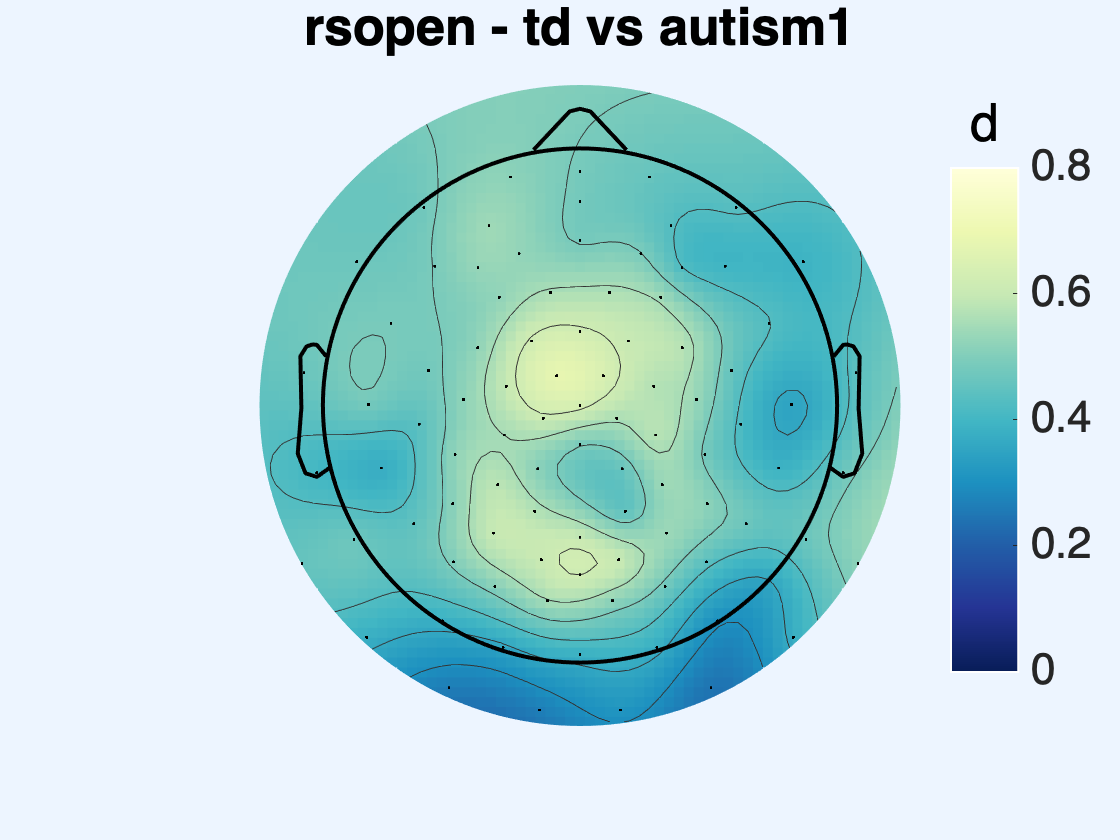

f1 = figure();
f1 = topoplot(dt_rseo.td_vs_a1_mean_d, chanlocs_struct, ...
    'electrodes', 'on', 'colormap', mycolormap); % [.2, .7]
cb = colorbar; clim([0, .8]); 
set(cb,'YTick', [0, .2, .4, .6, .8]); 
set(cb,'FontSize', cb_tick_sz);
set(cb,'position', cb_pos);
set(get(cb,'title'),'string','d', 'FontSize', cb_title_sz);
annotation('rectangle',cb.Position,'Color','w','FaceColor','none','LineWidth',1);
t = title('rsopen - td vs autism1'); t.FontSize = t_sz;
saveas(f1, fullfile(plotdir, 'rsopen/topoplots', '10_topoplot_mean_d_electH_tdva1.jpg'))

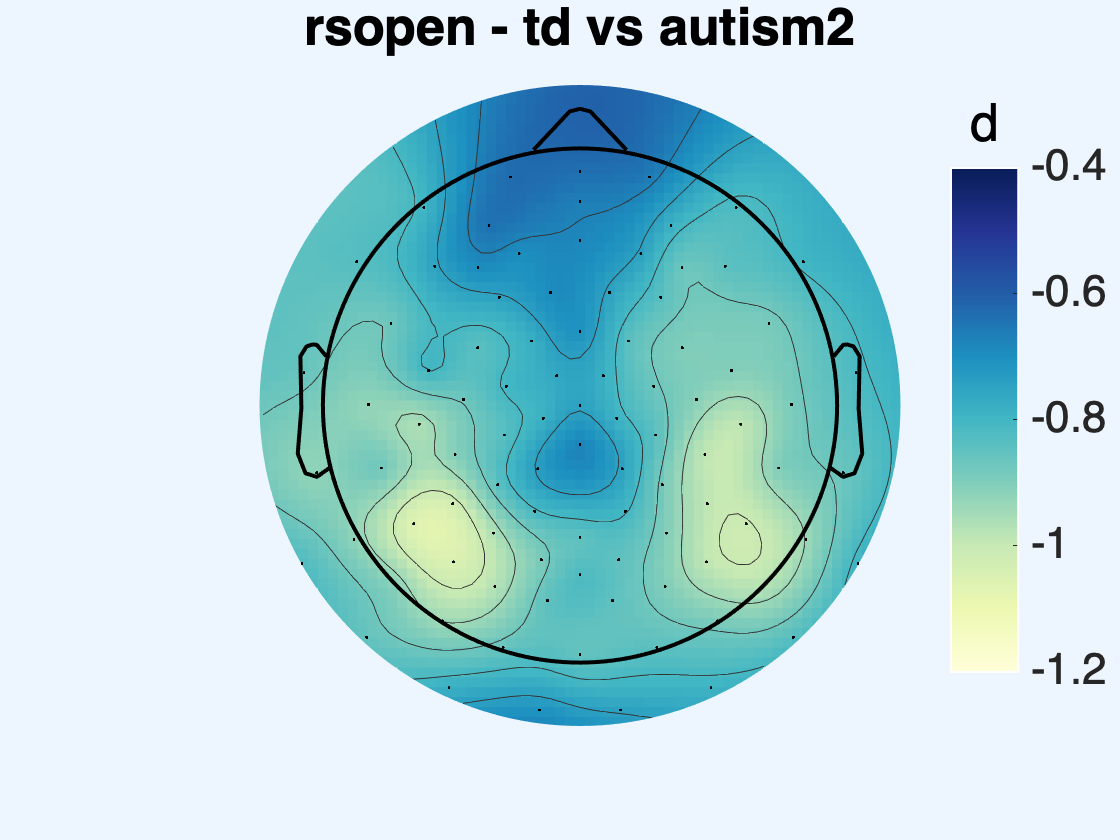


f2 = figure();
f2 = topoplot(dt_rseo.td_vs_a2_mean_d, chanlocs_struct, ...
    'electrodes', 'on', 'colormap', flip(mycolormap)); % [-.6, -1.1]
cb = colorbar; clim([-1.2, -.4]); 
set(cb,'YTick',[-1.2, -1, -.8, -.6, -.4]); 
set(cb,'FontSize', cb_tick_sz);
set(cb,'position', cb_pos);
set(get(cb,'title'),'string','d', 'FontSize', cb_title_sz);
annotation('rectangle',cb.Position,'Color','w','FaceColor','none','LineWidth',1);
t = title('rsopen - td vs autism2'); t.FontSize = t_sz;
saveas(f2, fullfile(plotdir, 'rsopen/topoplots', '10_topoplot_mean_d_electH_tdva2.jpg'))

## Plot resting state eyes closed 2 colors

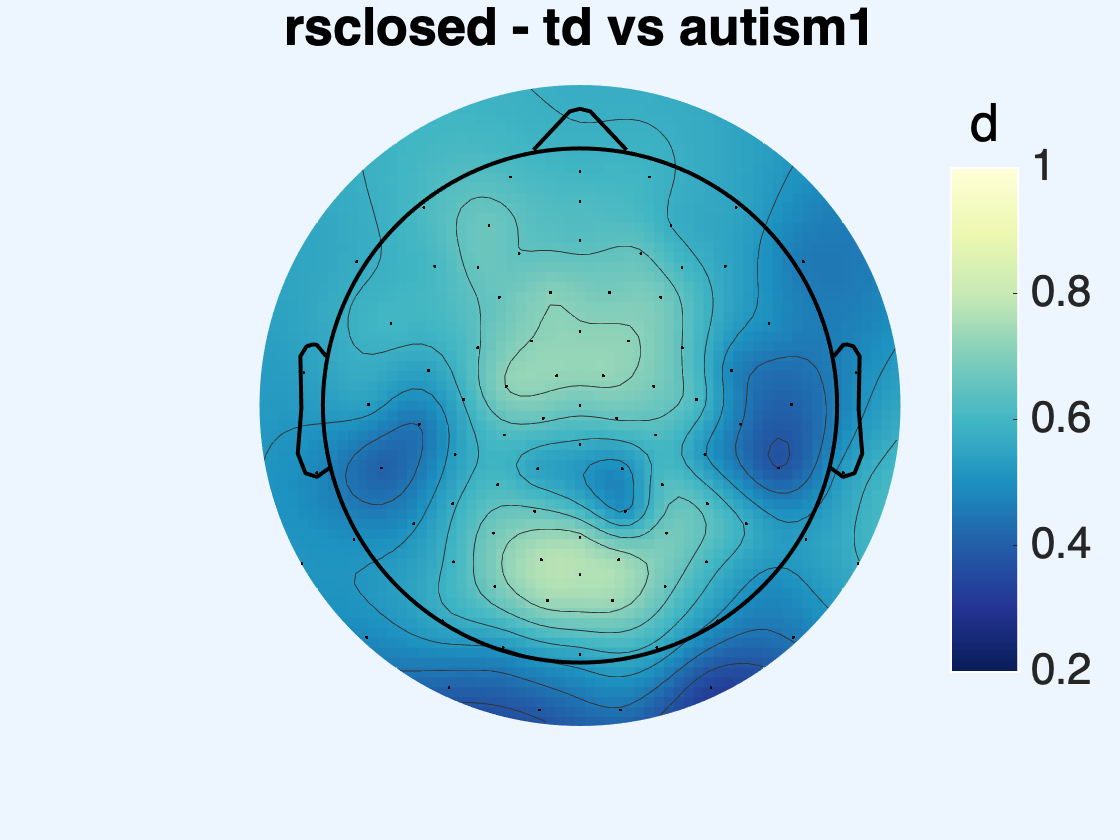

f3 = figure();
f3 = topoplot(dt_rsec.td_vs_a1_mean_d, chanlocs_struct, ...
'electrodes', 'on', 'colormap', mycolormap); % [.3, .8]
cb = colorbar; clim([.2, 1]); 
set(cb,'YTick', [.2, .4, .6, .8, 1]); 
set(cb,'FontSize', cb_tick_sz);
set(cb,'position', cb_pos);
set(get(cb,'title'),'string','d', 'FontSize', cb_title_sz);
annotation('rectangle',cb.Position,'Color','w','FaceColor','none','LineWidth', 1);
t = title('rsclosed - td vs autism1'); t.FontSize = t_sz;
saveas(f3, fullfile(plotdir, 'rsclosed/topoplots', '10_topoplot_mean_d_H_tdva1.jpg'))

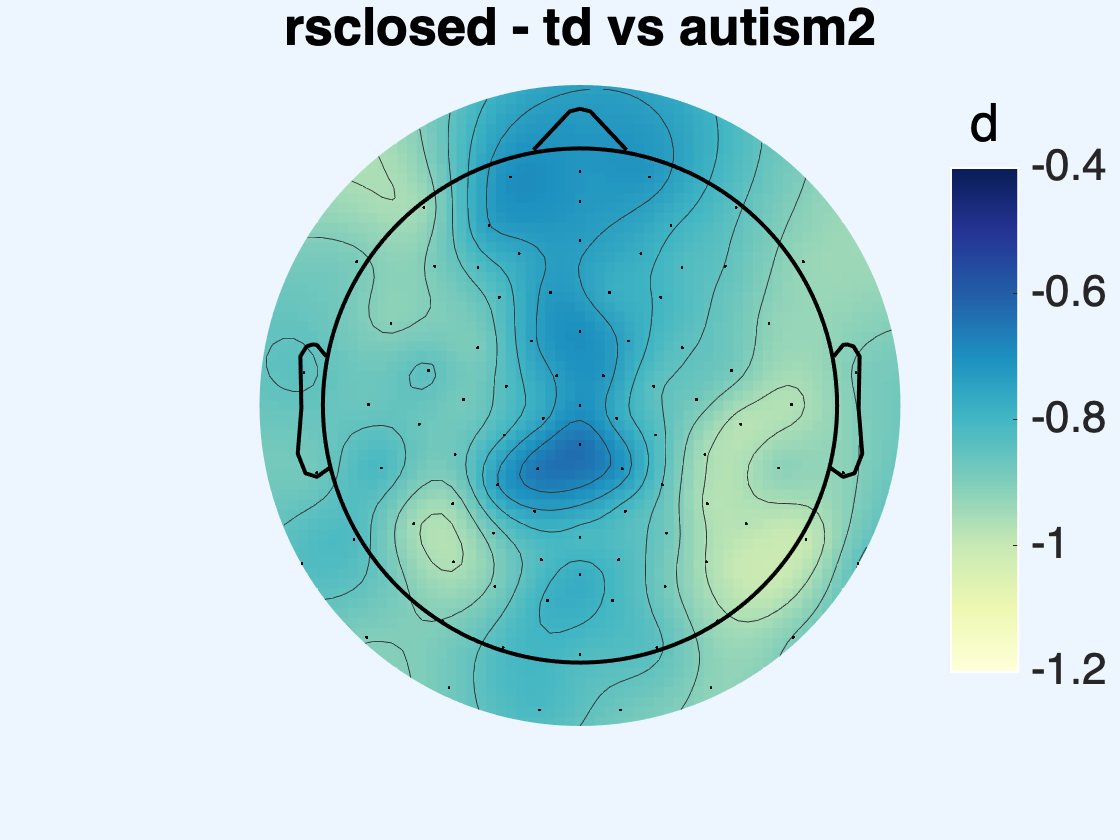


f4 = figure();
f4 = topoplot(dt_rsec.td_vs_a2_mean_d, chanlocs_struct, ...
    'electrodes', 'on', 'colormap', flip(mycolormap)); %[-1.1, -.6]
cb = colorbar; clim([-1.2, -.4]); 
set(cb,'YTick', [-1.2, -1, -.8, -.6, -.4]); 
set(cb,'FontSize', cb_tick_sz);
set(cb,'position', cb_pos);
set(get(cb,'title'),'string','d', 'FontSize', cb_title_sz);
annotation('rectangle',cb.Position,'Color','w','FaceColor','none','LineWidth',1);
t = title('rsclosed - td vs autism2'); t.FontSize = t_sz;
saveas(f4, fullfile(plotdir, 'rsclosed/topoplots', '10_topoplot_mean_d_H_tdva2.jpg'))

## rec H - rsopen PC4

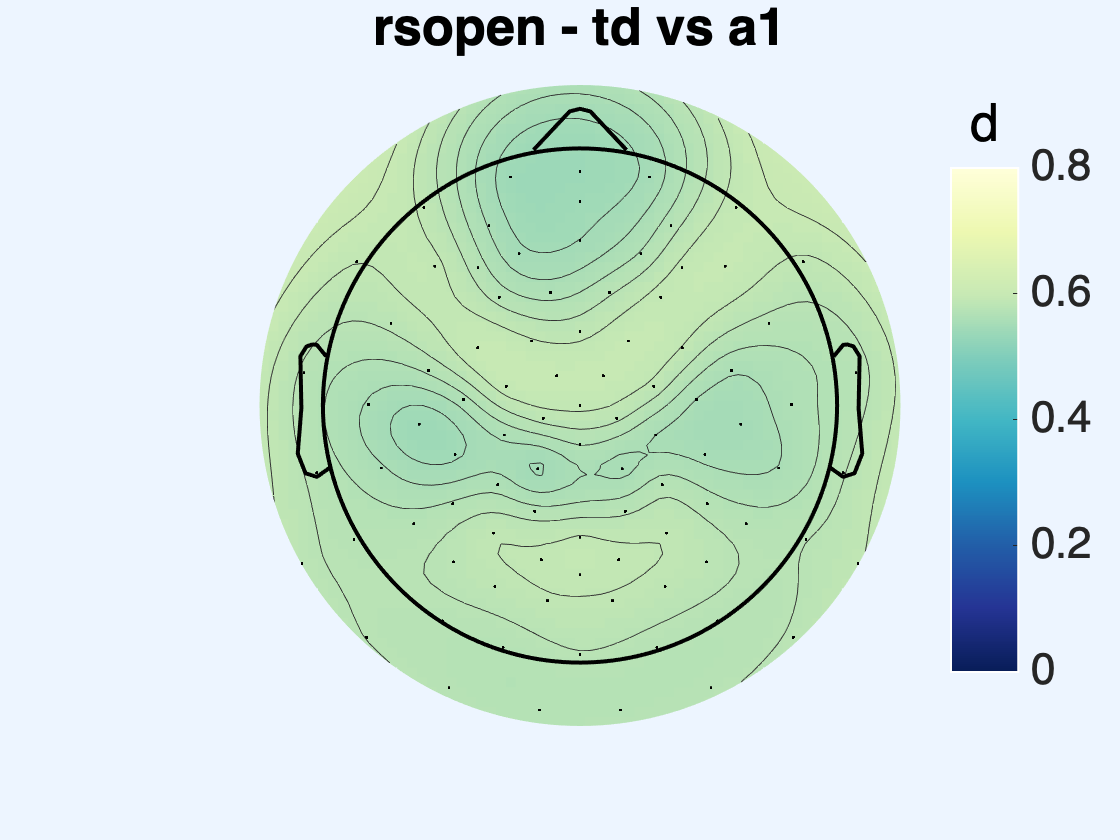

% plot td v a1
f5 = figure();
topoplot(dt_rseo_Hrec.td_vs_a1_mean_d, chanlocs_struct, ...
    'electrodes', 'on', 'colormap', mycolormap); %[-1.1, -.6]
cb = colorbar; clim([0, .8]); %.53-.60
set(cb,'YTick', [0, .2, .4, .6, .8]); 
set(cb,'FontSize', cb_tick_sz);
set(cb,'position', cb_pos);
set(get(cb,'title'),'string','d', 'FontSize', cb_title_sz);
annotation('rectangle',cb.Position,'Color','w','FaceColor','none','LineWidth',1);
t = title('rsopen - td vs a1'); t.FontSize = t_sz;
saveas(f5, fullfile(plotdir, 'rsopen/topoplots', '10_topoplot_mean_d_PC1&4recH_tdva1.jpg'))

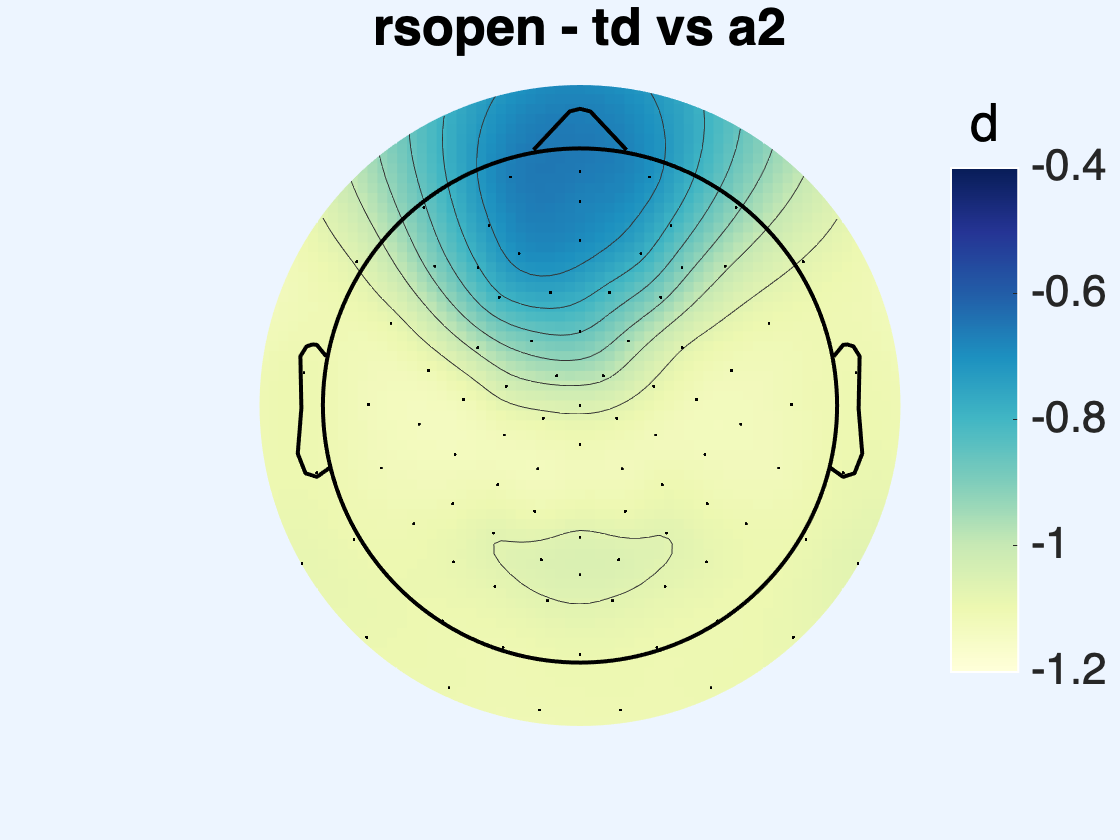


% plot td v a2
f6 = figure();
topoplot(dt_rseo_Hrec.td_vs_a2_mean_d, chanlocs_struct, ...
    'electrodes', 'on', 'colormap', flip(mycolormap)); 
cb = colorbar; clim([-1.2, -.4]);
set(cb,'YTick', [-1.2, -1, -.8, -.6, -.4, -.2, 0]); 
set(cb,'FontSize', cb_tick_sz);
set(cb,'position', cb_pos);
set(get(cb,'title'),'string','d', 'FontSize', cb_title_sz);
annotation('rectangle',cb.Position,'Color','w','FaceColor','none','LineWidth',1);
t = title('rsopen - td vs a2'); t.FontSize = t_sz;
saveas(f6, fullfile(plotdir, 'rsopen/topoplots', '10_topoplot_mean_d_PC1&4recH_tdva2.jpg'))